clc; clear all; close all;

#### Generating Random Data to Transmit

% Creating X_k - Randomly choose between 1 and -1
size_training_data = 640;
size_X = 6400; %Size of data - 100 sets of 64 bits
range = [-1 1]; %List of wanted values
a = randi(2,size_X,1); %Randomly select index
b = randi(2,size_training_data,1); 

Create Data and Training Data

X_k = transpose(range(a)); %Creates array with range(a) values
X_train = transpose(range(b)); %Training Data

#### IDFT - Takes inverse discrete fourier tranform of data

x_m = ifft(X_k); %Turns data points into impulses
x_train = ifft(X_train);

#### Extending each point by 64 points

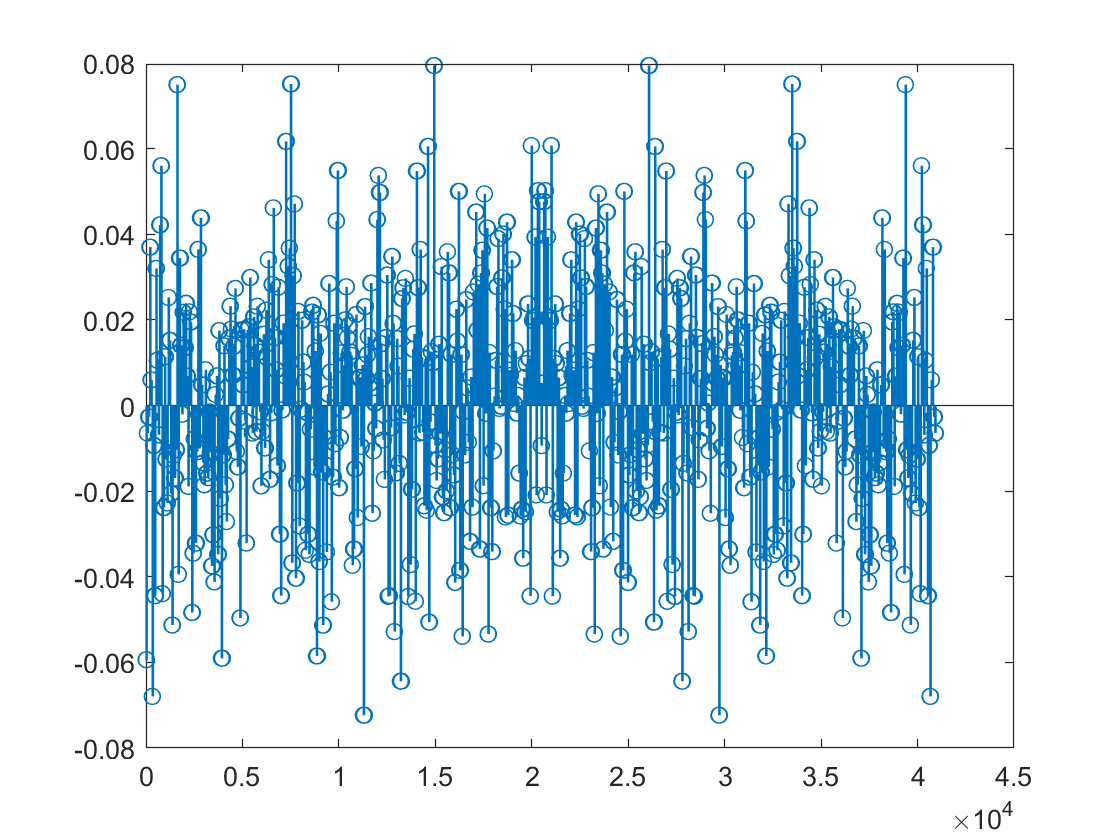

L = 64; %Length of Pulse - 64

pulse = ones(L, 1); %Creates pulse with L of 64 bits

x_0 = zeros(L*length(x_m),1);       % Creates "empty" vector that is lenght of desired data: 409600 bits
x_0(1:L:end) = x_m;                 % assign every Symbol_period-th sample to equal a value from bits
x_m_pulse = conv(pulse, x_0);       % Convolve vector by designed pulse
x_m_pulse= x_m_pulse(1:409600);     % Cut extra zeros caused by convolution - desired length of 409600 bits

x_t = zeros(L*length(x_train),1);       % Creates "empty" vector that is lenght of desired data: 409600 bits
x_t(1:L:end) = x_train;                 % assign every Symbol_period-th sample to equal a value from bits
x_train_pulse = conv(pulse, x_t);       % Convolve vector by designed pulse
x_train_pulse = x_train_pulse(1:L*length(x_train));     % Cut extra zeros caused by convolution - desired length of 409600 bits

figure(1)
stem(real(x_train_pulse))

#### Adding Cyclic Prefixes to Data

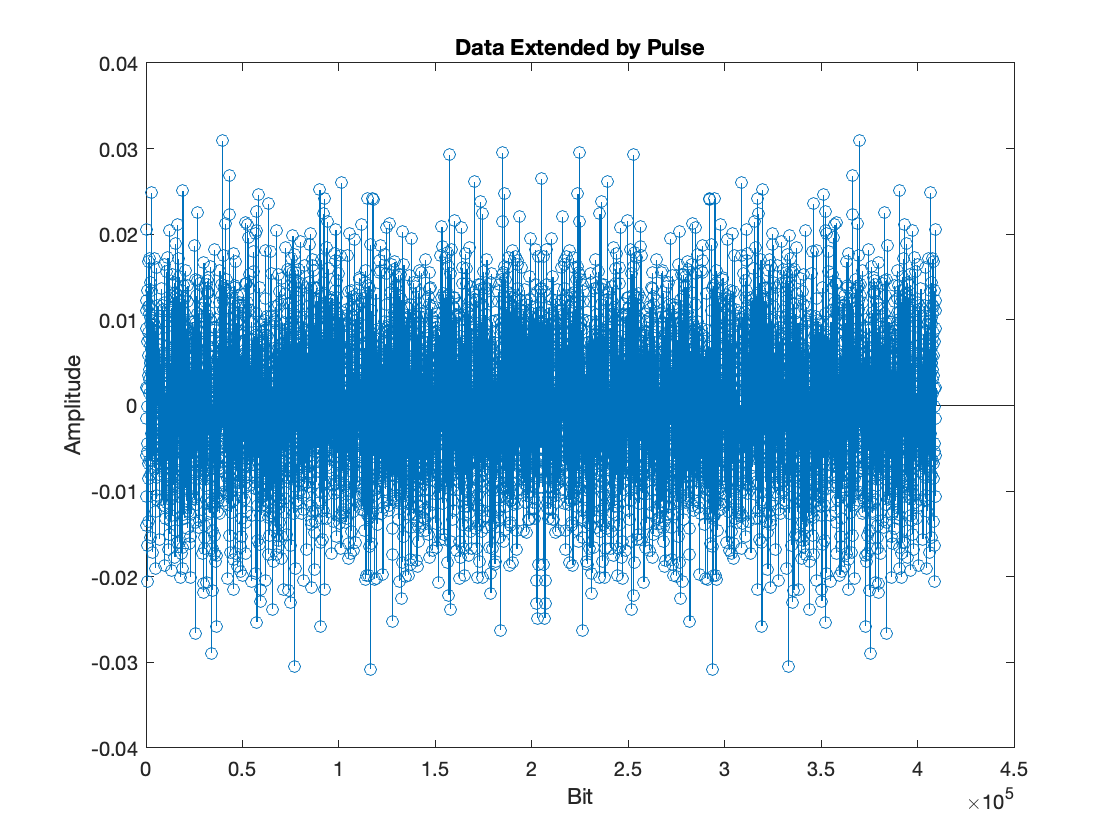

% Plot data
figure;
stem(real(x_m_pulse))
hold on
ylabel('Amplitude')
xlabel('Bit')
title('Data Extended by Pulse')
hold off

%%  Adding cyclic prefix
n_data = size_X / L; % Calculates amount of sets of d-bit data chunks from original data

Len_pulse_data = length(x_m_pulse) + length(x_m_pulse)/4; % Calculates Desired final length of data w/ cyclic prefix

%Index 1st cyclic prefix - Done to ensure methodology works
cycPrefix = x_m_pulse(3073: 4096);                  % Determines index of first cyclic prefix - 1024 bits
x_m_load(1:1024) = cycPrefix;                       % Initializes array that will hold data w/ prefix, making first 1024 valus the cyclic prefix
x_m_load(1025:5120) = x_m_pulse(1: 4096);           % Loads first set of data, 64 bits -> 4096 bits 

%Index the Remaining Data
for R = 2:1:n_data   % Adds cyclic prefixes
    cycPrefix = x_m_pulse(4096*(R-1)+ 64*48+1: 4096*(R)); 
    x_m_load(80*64*(R-1)+1 : 5120*(R-1) + 1024) = cycPrefix;
    Post_chunk =  x_m_pulse(4096*(R-1)+1: 4096*(R));
    x_m_load(5120*(R-1) + 1024+1 : 5120*(R-1) + 1024 +4096) = Post_chunk;
end
% -------------------------TRAINING DATA--------------------------

Len_pulse_train = length(x_train_pulse) + length(x_train_pulse)/4; % Calculates Desired final length of data w/ cyclic prefix

%   For Training data Index 1st cyclic prefix - Done to ensure methodology works
cycPrefix_train = x_train_pulse(3073: 4096);                  % Determines index of first cyclic prefix - 1024 bits
x_train_load(1:1024) = cycPrefix;                       % Initializes array that will hold data w/ prefix, making first 1024 valus the cyclic prefix
x_train_load(1025:5120) = x_train_pulse(1: 4096);           % Loads first set of data, 64 bits -> 4096 bits 

%Index the Remaining Data
for R = 2:1:(size_training_data/L)   % Adds cyclic prefixes
    cycPrefix_train = x_train_pulse(4096*(R-1)+ 64*48+1: 4096*(R)); 
    x_train_load(80*64*(R-1)+1 : 5120*(R-1) + 1024) = cycPrefix_train;
    Post_chunk =  x_train_pulse(4096*(R-1)+1: 4096*(R));
    x_train_load(5120*(R-1) + 1024+1 : 5120*(R-1) + 1024 +4096) = Post_chunk;
end

#### Check Cyclic Prefix

% -------------------------TRAINING DATA--------------------------

Len_pulse_train = length(x_train_pulse) + length(x_train_pulse)/4; % Calculates Desired final length of data w/ cyclic prefix

%   For Training data Index 1st cyclic prefix - Done to ensure methodology works
cycPrefix_train = x_train_pulse(3073: 4096);                  % Determines index of first cyclic prefix - 1024 bits
x_train_load(1:1024) = cycPrefix;                       % Initializes array that will hold data w/ prefix, making first 1024 valus the cyclic prefix
x_train_load(1025:5120) = x_train_pulse(1: 4096);           % Loads first set of data, 64 bits -> 4096 bits 

%Index the Remaining Data
for R = 2:1:(size_training_data/L)   % Adds cyclic prefixes
    cycPrefix_train = x_train_pulse(4096*(R-1)+ 64*48+1: 4096*(R)); 
    x_train_load(80*64*(R-1)+1 : 5120*(R-1) + 1024) = cycPrefix_train;
    Post_chunk =  x_train_pulse(4096*(R-1)+1: 4096*(R));
    x_train_load(5120*(R-1) + 1024+1 : 5120*(R-1) + 1024 +4096) = Post_chunk;
end

% Downsample from x_m_load
Data_6400cyc = downsample(x_train_load,64);
ret = transpose(fft(Data_6400cyc));
ret = ret(1:length(X_train));
diff = real((real(X_train) - (real(ret)./abs(real(ret)))))./(2*real(X_train));
Error = abs(mean(diff)) *100

Error = 47.8125

#### Transmitting Data through nonflat channel function

Transmitting Training Data

%Transpose the Data - 1x51200 -> 51200x1
x_train_load = transpose(x_train_load);

% Transmit data through nonflat channel function
y_m_train = nonflat_channel(x_train_load);

Compensating for time delay

% Determine Lag in Data
[y1x1_train,lag1] = xcorr(y_m_train,x_train_load); 
[~, Index1_train] = max(abs(y1x1_train));
shift1_train = lag1(Index1_train);
%Comes out to be 9

%Cut Data from Lag
y_m_train = y_m_train(shift1_train:end);

Transmitting Data

% Transpose the Data - 1x51200 -> 51200x1
x_m_load = transpose(x_m_load);

% Transmit data through nonflat channel function
y_m = nonflat_channel(x_m_load);


Compensating for time delay

[y1x1,lag1] = xcorr(y_m,x_m_load); 
[~, Index1] = max(abs(y1x1));
shift1 = lag1(Index1);
%Comes out to be 9

%Cut Data from Lag
y_m = y_m(shift1:end);

Sending Empty set for Noise Calculation of Channel

zero_noise = zeros(length(x_train_load),1);
noise_thru_channel = nonflat_channel(zero_noise);

#### Retrieving 6400 data bits from received signal

Move received time signal to the frequency domain using FFT

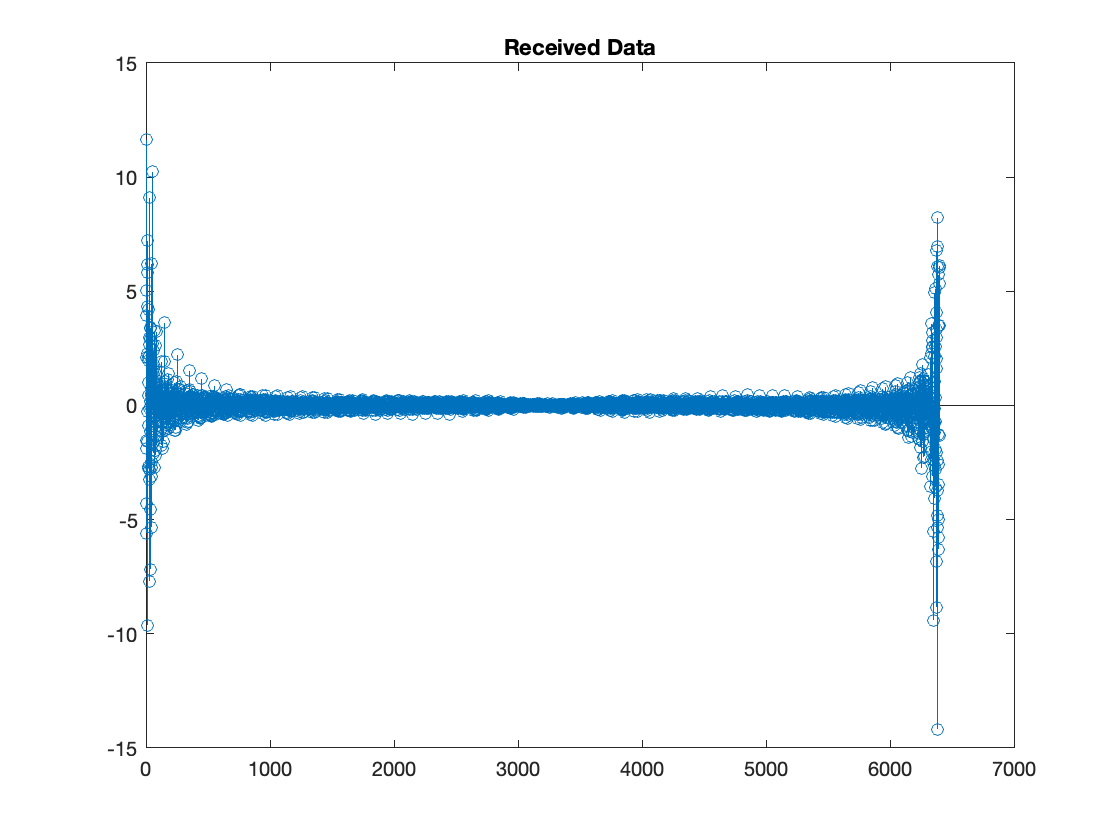

%% FFT - Fast Fourier Transform of Received Data
Y_k = fft(y_m,size_X);
Y_k_train = fft(y_m_train,size_training_data);

figure;
stem(real(Y_k));
hold on
title('Received Data')
hold off

Channel Estimation 

With OFDM, we are assuming flat fading model for every 64 bits of data, giving us 100 different transfer functions

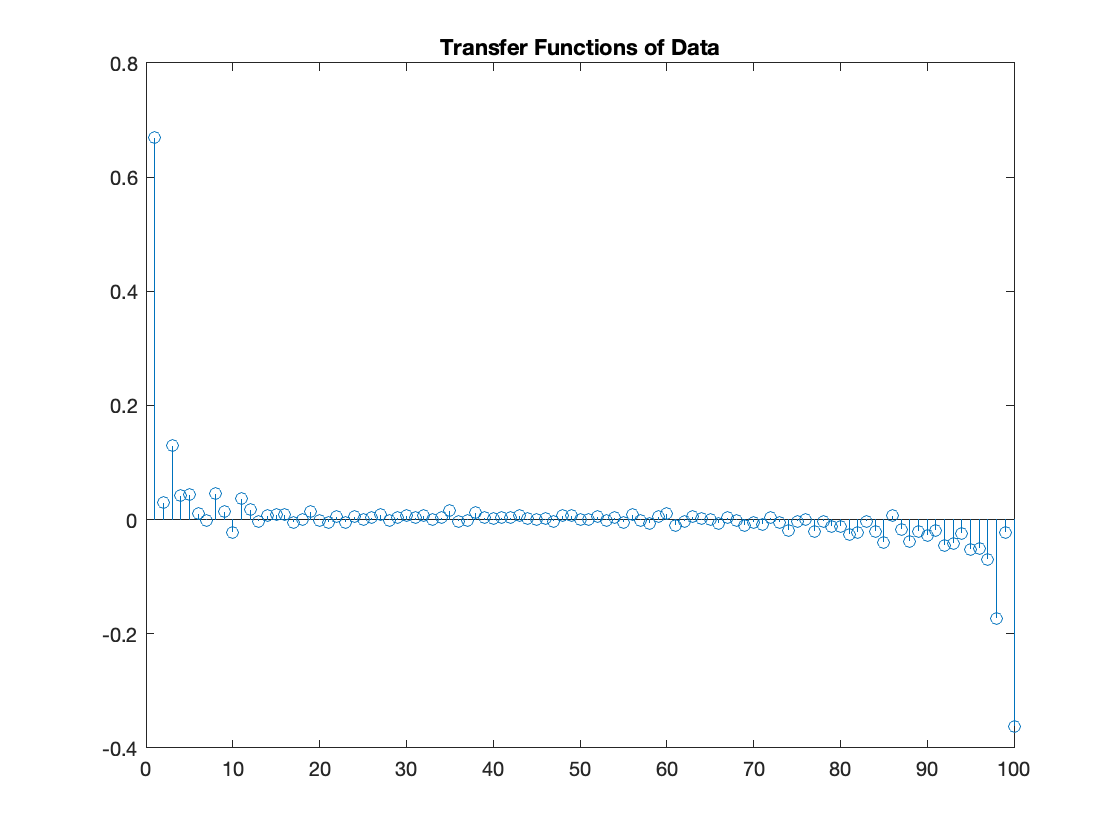

H_k = zeros(100,1); %Empty vector to put transfer function values

for H = 1:1:n_data   % For each chunk of 64 -> 100 in total
    ChannelEst_n = mean(Y_k(1 + 64*(H-1): 64*(H))); % Calculates transfer function for every 64 bits (assuming flat fading model)
    H_k(H) = ChannelEst_n; %Place data into Transfer function matrix
end
figure;
stem(real(H_k));
hold on
title('Transfer Functions of Data');
hold off

Estimation of Noise

est_noise = var(noise_thru_channel)

est_noise = 0


for Z = 1:1:n_data   % For each chunk of 64 -> 100 in total
    w = ((conj(H_k(Z))));
    Y_ret = (conj(w)).*(Y_k(1 + 64*(Z-1): 64*(Z))); % Calculates transfer function for every 64 bits (assuming flat fading model)
    Retrieved_data(1 + 64*(Z-1): 64*(Z)) = Y_ret; %Place data into Transfer function matrix
end
Retrieved_data = transpose(Retrieved_data)

Retrieved_data =    7.5533 - 3.4282i
  -3.0068 + 3.4565i
   2.2904 - 4.2955i
  -3.9743 - 2.2069i
   3.7687 + 2.2850i
   0.7616 - 2.3170i
   0.9447 + 5.9808i
  -2.9714 - 4.4556i
   1.0562 + 3.6312i
  -1.2451 - 0.2066i


#### Transmitted Vs Received Data

% Calculating Error

% diff = real((real(X_k) - (real(Y_k)./abs(real(Y_k)))))./real(X_k);
diff = real((real(X_k) - (real(Y_k)./abs(real(Y_k)))))./(2*real(X_k));
% num_error = length(diff(diff==2));
Error = abs(mean(diff)) *100

Error = 49.9844

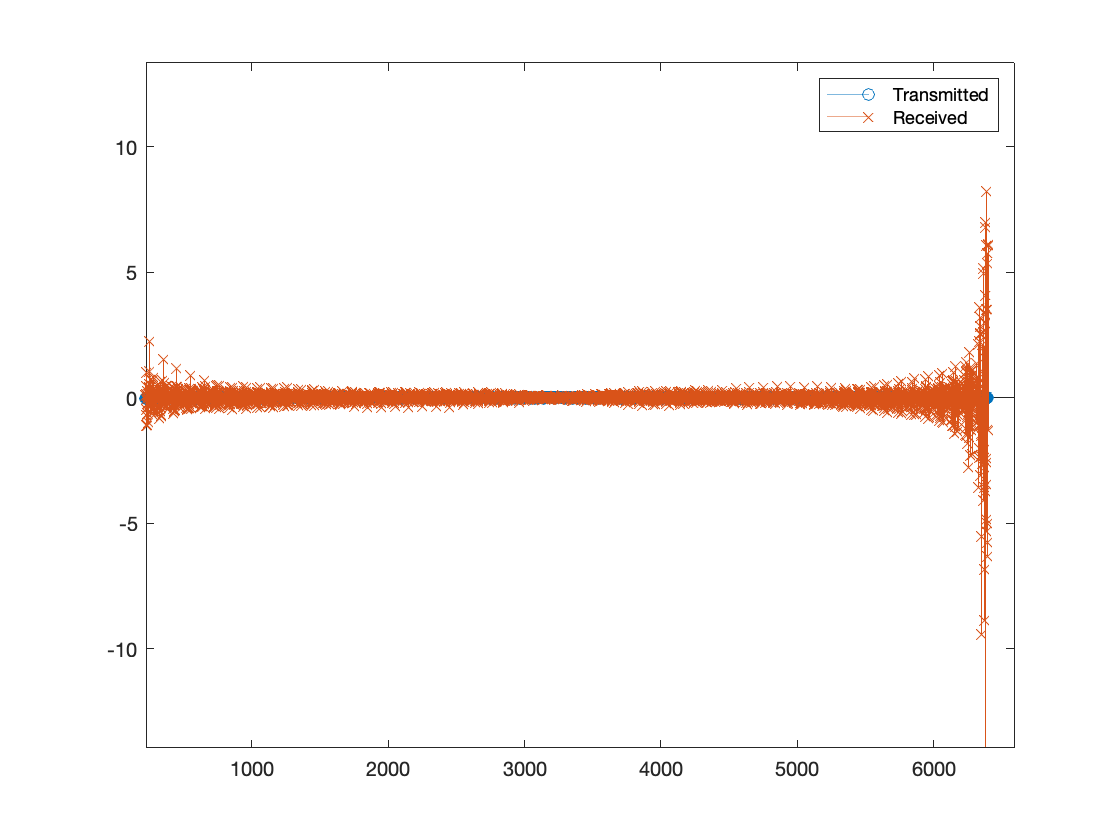


%Plotting Data
stem(real(x_m),'o') % Plotting Transmitted Data
hold on
stem(real(Y_k),'x')% Plotting Received Data
legend('Transmitted','Received')
hold off


% Calculating Error

% diff = real((real(X_k) - (real(Y_k)./abs(real(Y_k)))))./real(X_k);
diff = real((real(X_k) - (real(Retrieved_data)./abs(real(Retrieved_data)))))./(2*real(X_k));
% num_error = length(diff(diff==2));
Error = abs(mean(diff)) *100

Error = 48.5469

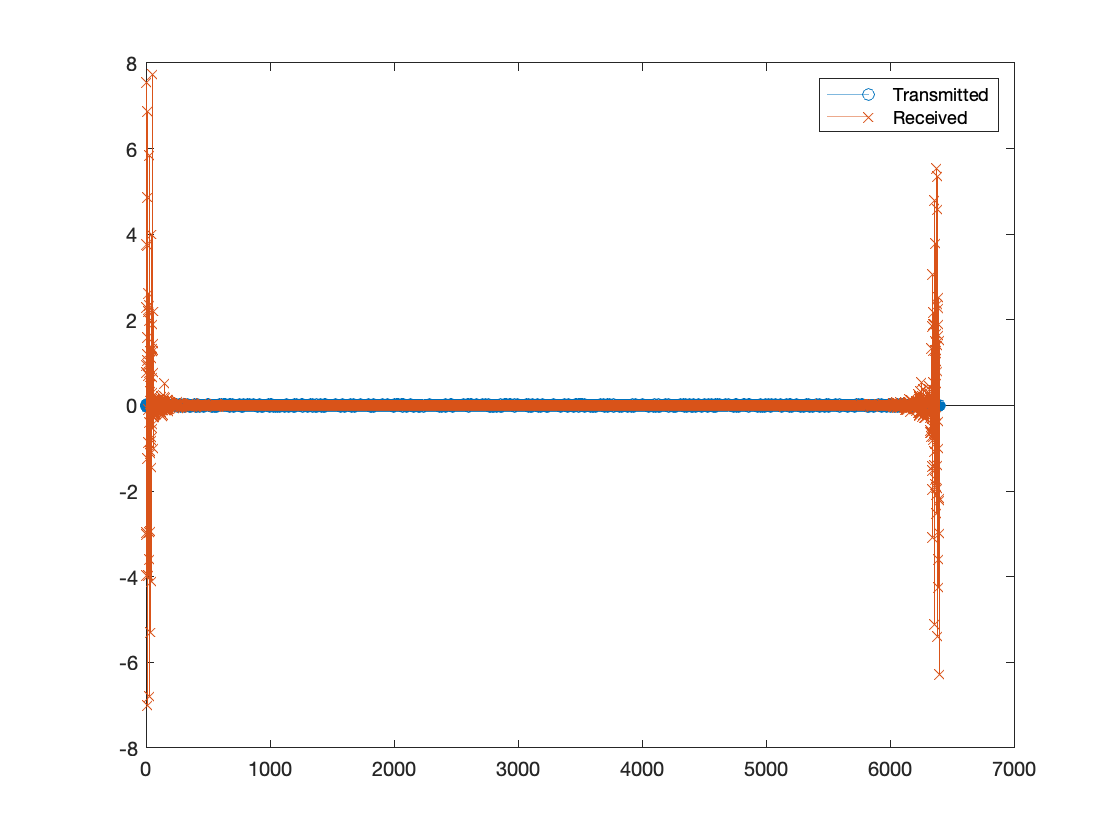


%Plotting Data
stem(real(x_m),'o') % Plotting Transmitted Data
hold on
stem(real(Retrieved_data),'x')% Plotting Received Data
legend('Transmitted','Received')
hold off